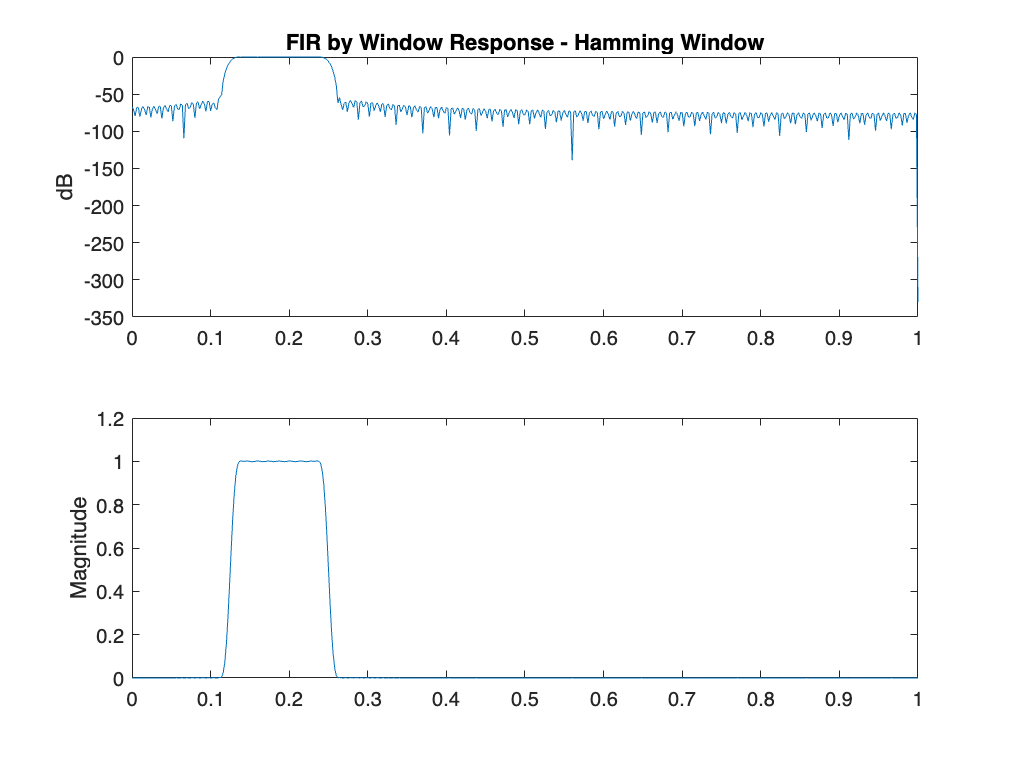

% x_a is bandlimited to 1000 Hz. Minimum sampling frequency is 2000 Hz
% double that is 4000 Hz
%
% Fs = 4000
% Fs/2 = 2000 is mapped to pi
%
% 1 kHz is mapped to pi/2
% 500 Hz is mapped to pi/4
% 250 Hz is mapped to pi/8

% Decimation by 4 will "expand" the occupied bandwidth by the signal
% pi/2 will become 2*pi
% pi/4 will become pi
% pi/8 will become pi/2
%
% If we want to keep only the frequencies of interest, we must
% use a bandpass filter, between pi/8 (0.125pi) to pi/4 (0.25pi)

% so to create the bandpass, we should have ideal_lp(pi/4, M) -
% ideal_lp(pi/8)
% The length of the filter can be estimated via the transition width
% of pi/50. 
% From presentation 17, slide 26, we can use
% M = 8 * pi/(pi/50) = 400
M = 400;
M = 296; % this lower value meets the spec
wc2 = pi/4;
wc1 = pi/8;
df = 0.02*pi;
hd = ideal_lp(wc2,M) - ideal_lp(wc1, M);
hm = hamming(M)';
h = hd .* hm;
[db,mag,pha,grd,w] = freqz_m(h,[1]);
delta_w = 2*pi/1000;
figure;
subplot(2,1,1);
plot(w/pi,db);
ylabel('dB');
title('FIR by Window Response - Hamming Window')
subplot(2,1,2);
plot(w/pi, mag);
ylabel('Magnitude')

ws1 = wc1 - (df/2);
ws2 = wc2 + (df/2);
filter_length = M

filter_length = 296

As = -round(max(db(1:1:ws1/delta_w-1))) % Min Stopband attenuation for first stopband

As = 57

As2 = -round(max(db(ws2/delta_w+1:1:501))) % Min Stopband attenuation for second stopband

As2 = 40

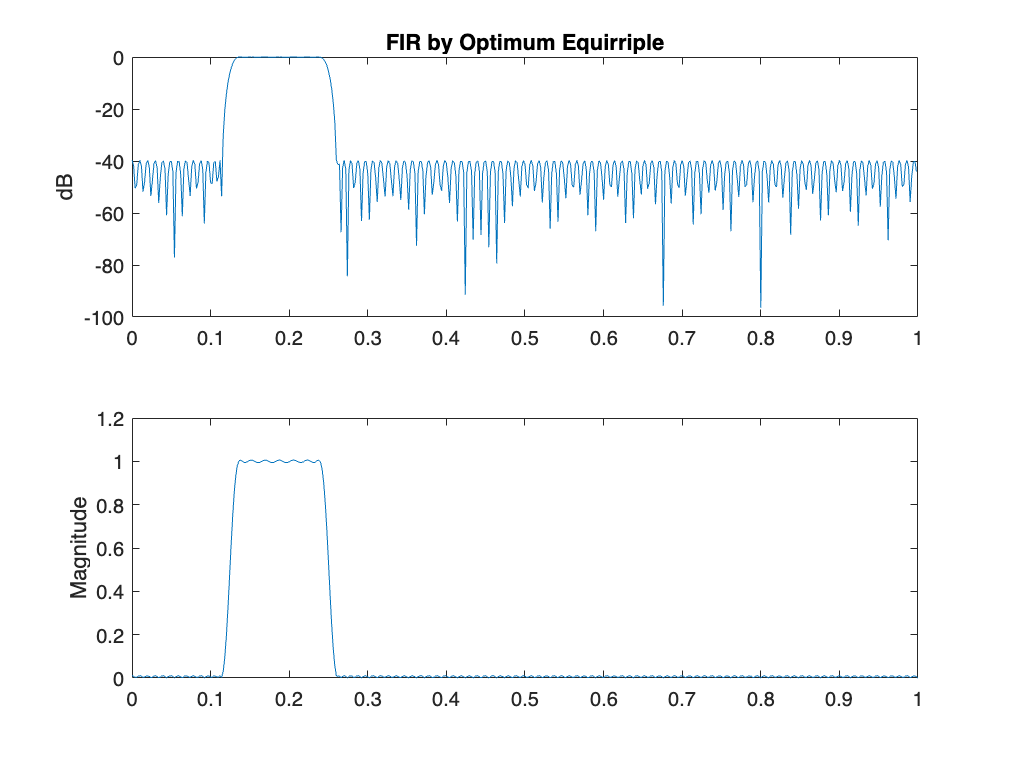

% the attenuation meets the specs

% If we want to use optimum equirripple design, we can use a value of Rp =
% 1 dB
Rp = 0.1;
As = 40;
wp1 = wc1 + (df/2);
wp2 = wc2 - (df/2);
f = [ ws1 wp1 wp2 ws2 ] ./ pi;
a = [0 1 0];
d1 = (1-db2mag(-Rp))/(1+db2mag(-Rp));
d2 = db2mag(-As)*(1+d1);
d = [d2 d1 d2];
[M, fo, ao, W] = firpmord(f,a,d);
h = firpm(M, fo, ao, W);
[db, mag, pha, grd, w] = freqz_m(h,[1]);
figure;
subplot(2,1,1);
plot(w/pi,db);
ylabel('dB');
title('FIR by Optimum Equirriple')
subplot(2,1,2);
plot(w/pi, mag);
ylabel('Magnitude')

filter_length = M

filter_length = 211

As = -round(max(db(1:1:ws1/delta_w-1))) % Min Stopband attenuation for first stopband

As = 40

As2 = -round(max(db(ws2/delta_w+1:1:501))) % Min Stopband attenuation for second stopband

As2 = 40

clear;
wc = 0.7*pi;
df = 0.1*pi;
ws = wc - (df/2);
wp = wc + (df/2);
As = 50;
As = 60; % to meet the 50 dB attenuation above
Rp = 1;

% Analog Prototype Specifications: Inverse mapping for frequencies
T = 1; Fs = 1/T;
OmegaS = (2/T)*tan(wp/2); % we switch the design parameters as butterworth is lowpass
OmegaP = (2/T)*tan(ws/2); 

% Analog Butterworth Prototype Filter Calculation:
[cs,ds] = afd_butt(OmegaP,OmegaS,Rp,As);


*** Butterworth Filter Order = 20 


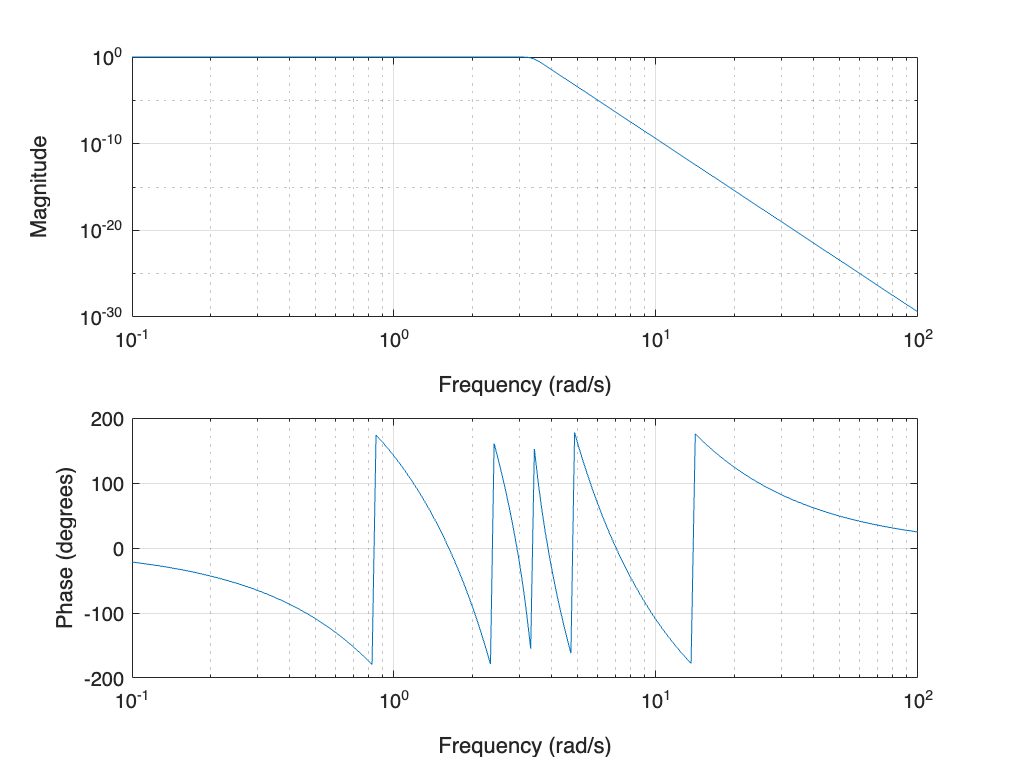

freqs(cs,ds)

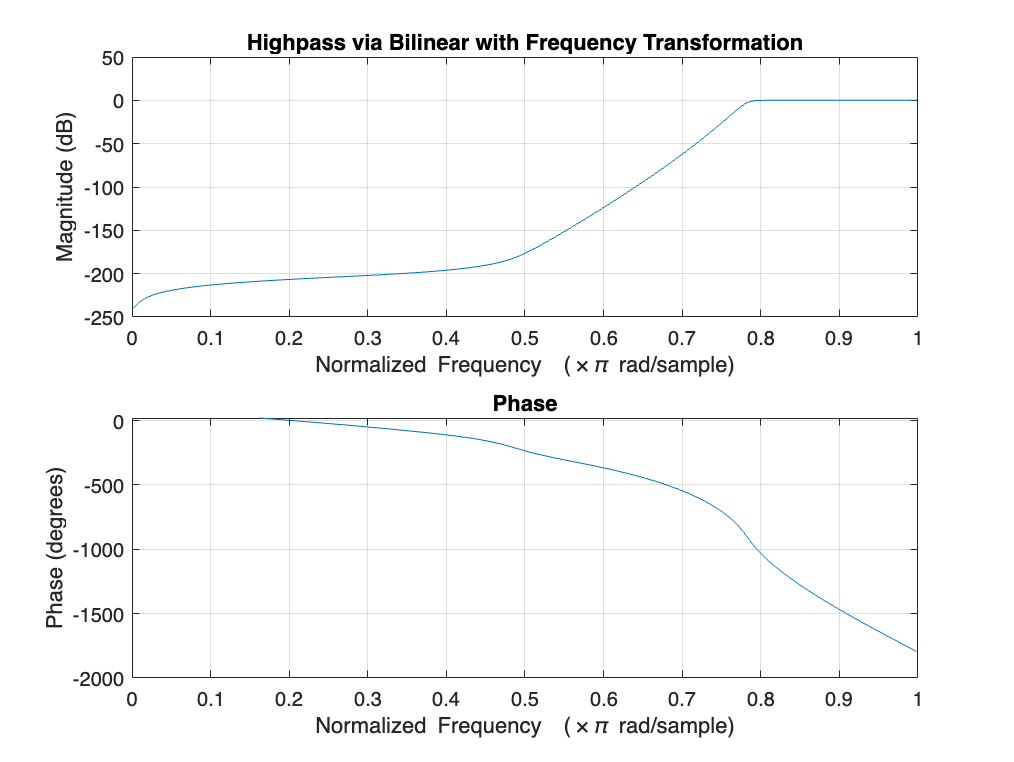

% Bilinear transformation:
[bl,al] = bilinear(cs,ds,Fs);

% We need to find the highpass mapping
% from slide presentation 21, slide 11
wphp = 0.7*pi;
a = -cos((wp + wphp)/2)/cos((wp - wphp)/2);
Nz = -[a 1];
Dz = [1 a];

[bh,ah] = zmapping(bl,al,Nz,Dz);
figure;
freqz(bh,ah);
title('Highpass via Bilinear with Frequency Transformation')

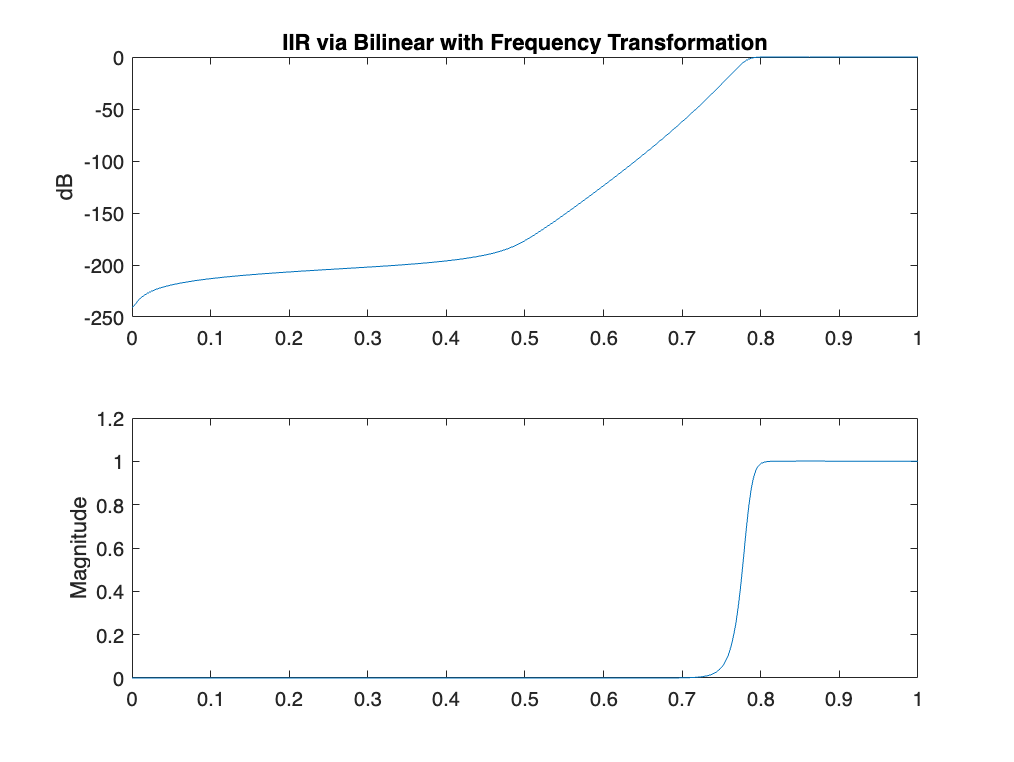


[db, mag, pha, grd, w] = freqz_m(bh,ah);
figure;
subplot(2,1,1);
plot(w/pi,db);
ylabel('dB');
title('IIR via Bilinear with Frequency Transformation')
subplot(2,1,2);
plot(w/pi, mag);
ylabel('Magnitude')

wsh = wphp;
delta_w = 2*pi/1000;
filter_order = length(ah)

filter_order = 21

As = -round(max(db(1:1:wsh/delta_w-1))) % Min Stopband attenuation for first stopband

As = 65

clear;
wc = 0.7*pi;
df = 0.1*pi;
ws = wc - (df/2);
wp = wc + (df/2);
As = 50;
As = 60; % to meet the 50 dB attenuation above
Rp = 1;

% Analog Prototype Specifications
T = 1; Fs = 1/T;
OmegaS = wp/T; % we switch the design parameters as butterworth is lowpass
OmegaP = ws/T;

% Analog Butterworth Prototype Filter Calculation:
[cs,ds] = afd_butt(OmegaP,OmegaS,Rp,As);


*** Butterworth Filter Order = 53 


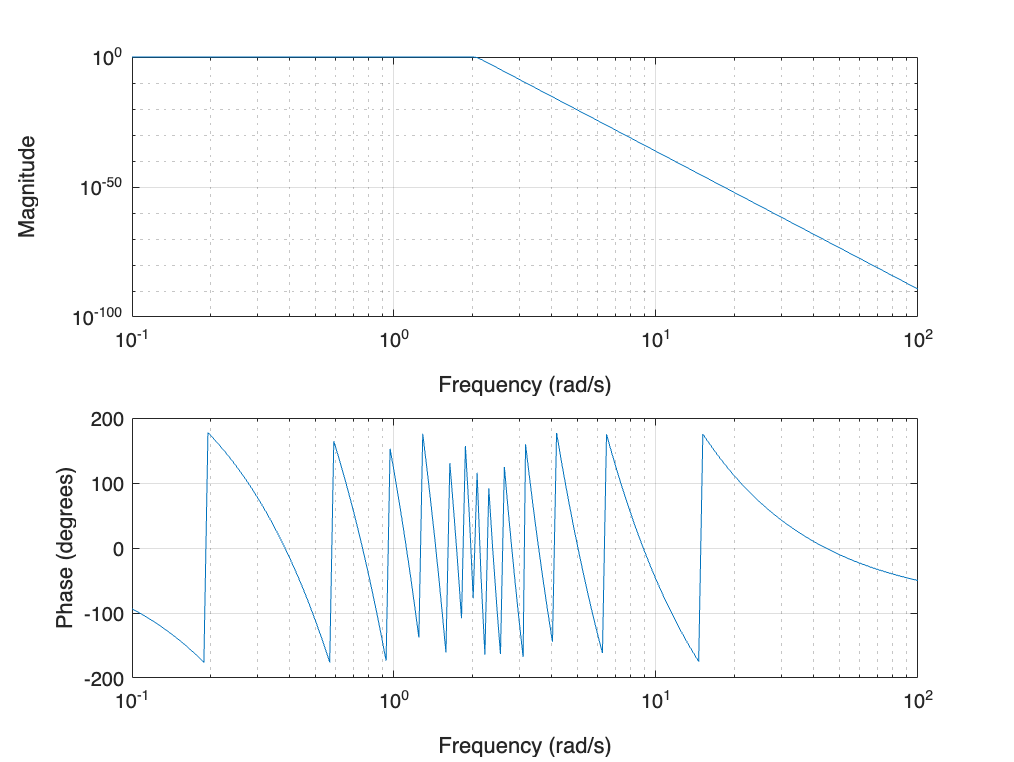

freqs(cs,ds)

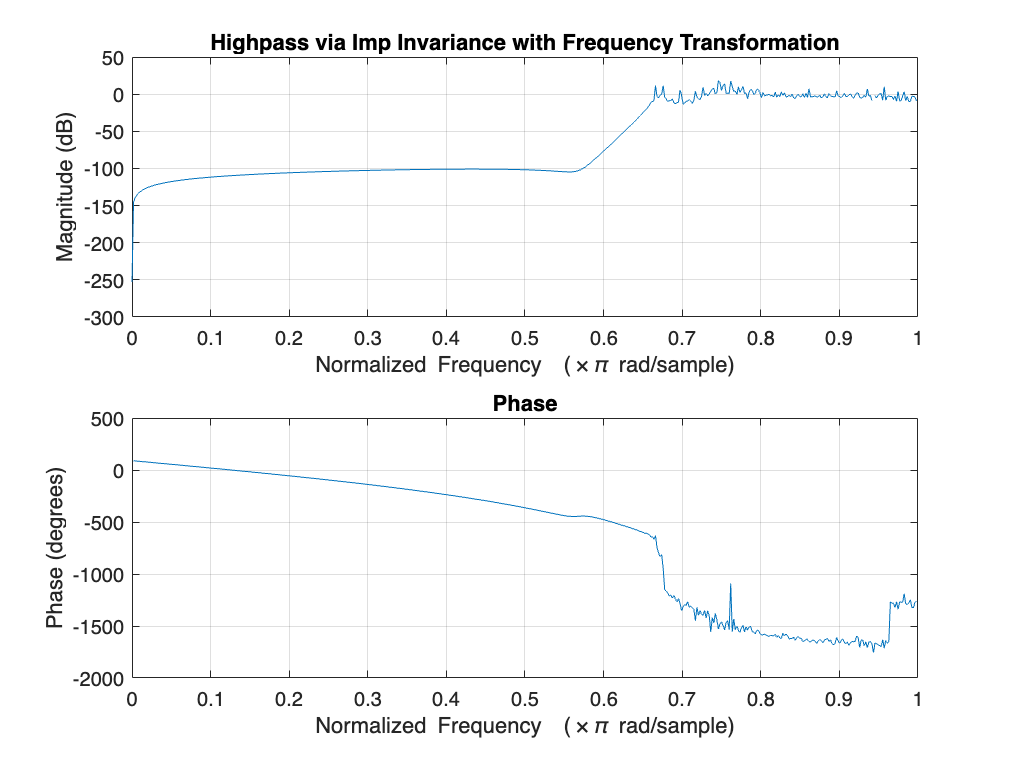


% Impulse Invariance transformation:
[bl,al] = bilinear(cs,ds,Fs);

% We need to find the highpass mapping
% from slide presentation 21, slide 11
wphp = 0.7*pi;
a = -cos((wp + wphp)/2)/cos((wp - wphp)/2);
Nz = -[a 1];
Dz = [1 a];

[bh,ah] = zmapping(bl,al,Nz,Dz);
figure;
freqz(bh,ah);
title('Highpass via Imp Invariance with Frequency Transformation')

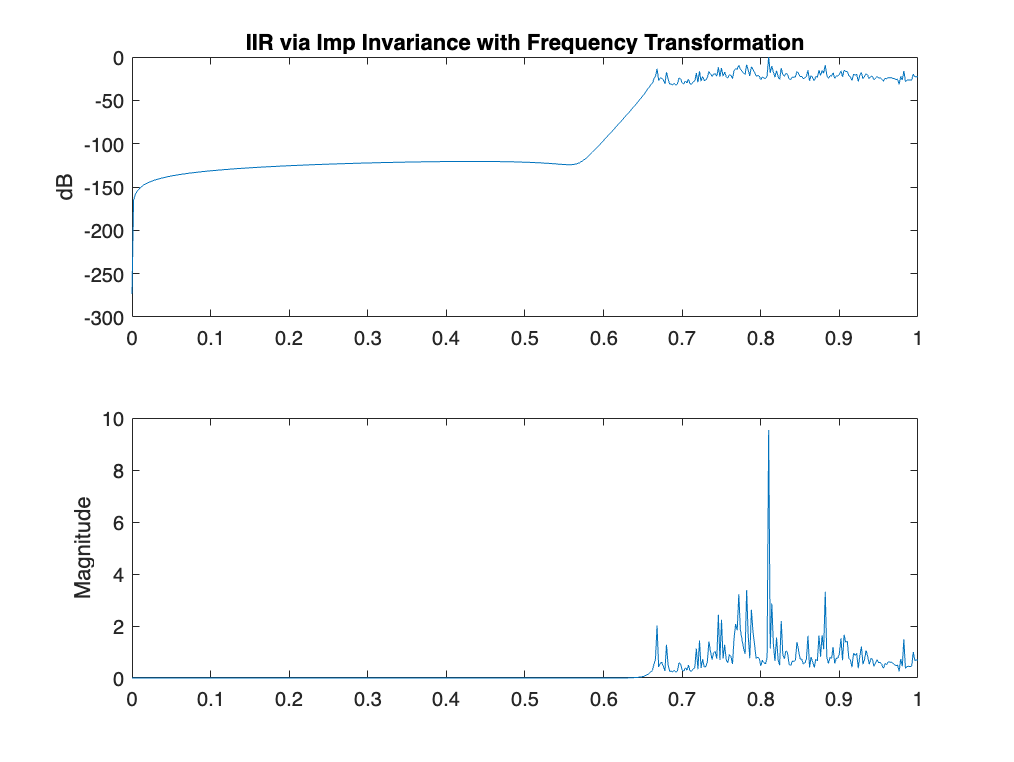


[db, mag, pha, grd, w] = freqz_m(bh,ah);
figure;
subplot(2,1,1);
plot(w/pi,db);
ylabel('dB');
title('IIR via Imp Invariance with Frequency Transformation')
subplot(2,1,2);
plot(w/pi, mag);
ylabel('Magnitude')

wsh = wphp;
delta_w = 2*pi/1000;
filter_order = length(ah)

filter_order = 54

As = -round(max(db(1:1:wsh/delta_w-1))) % Min Stopband attenuation for first stopband

As = 13

function hd = ideal_lp(wc, M); 
% Ideal LowPass filter computation 
% -------------------------------- 
% [hd] = ideal_lp(wc,M) 
% hd = ideal impulse response between 0 to M-1 
% wc = cutoff frequency in radians 
% M = length of the ideal filter
%
L = (M-1)/2; n = [0:1:(M-1)]; 
m = n - L; fc2 = wc/pi; hd = fc2*sinc(fc2*m); 
end

function [db,mag,pha,grd,w] = freqz_m(b,a); 
% Modified version of freqz subroutine 
% ------------------------------------ 
% [db,mag,pha,grd,w] = freqz_m(b,a); 
% db = Relative magnitude in dB computed over 0 to pi radians 
% mag = absolute magnitude computed over 0 to pi radians 
% pha = Phase response in radians over 0 to pi radians 
% grd = Group delay over 0 to pi radians 
% w = 501 frequency samples between 0 to pi radians 
% b = numerator polynomial of H(z) (for FIR: b=h) 
% a = denominator polynomial of H(z) (for FIR: a=[1]) 
%
[H,w] = freqz(b,a,1000,'whole'); 
H = (H(1:1:501))'; w = (w(1:1:501))';
mag = abs(H); 
db = 20*log10((mag)/max(mag)); 
pha = angle(H); 
grd = grpdelay(b,a,w); 
end

function [b,a] = afd_butt(Wp,Ws,Rp,As);
% Analog Lowpass Filter Design: Butterworth
% -----------------------------------------
% [b,a] = afd_butt(Wp,Ws,Rp,As);
%  b = Numerator coefficients of Ha(s)
%  a = Denominator coefficients of Ha(s)
% Wp = Passband edge frequency in rad/sec; Wp > 0
% Ws = Stopband edge frequency in rad/sec; Ws > Wp > 0
% Rp = Passband ripple in +dB; (Rp > 0)
% As = Stopband attenuation in +dB; (As > 0)
%
if Wp <= 0
        error('Passband edge must be larger than 0')
end
if Ws <= Wp
        error('Stopband edge must be larger than Passband edge')
end
if (Rp <= 0) | (As < 0)
        error('PB ripple and/or SB attenuation ust be larger than 0')
end
N = ceil((log10((10^(Rp/10)-1)/(10^(As/10)-1)))/(2*log10(Wp/Ws)));
fprintf('\n*** Butterworth Filter Order = %2.0f \n',N)
OmegaC = Wp/((10^(Rp/10)-1)^(1/(2*N)));
[b,a]=u_buttap(N,OmegaC);
end

function [b,a] = u_buttap(N,Omegac);
% Unnormalized Butterworth Analog Lowpass Filter Prototype
% --------------------------------------------------------
% [b,a] = u_buttap(N,Omegac);
%      b = numerator polynomial coefficients of Ha(s)
%      a = denominator polynomial coefficients of Ha(s)
%      N = Order of the Butterworth Filter
% Omegac = Cutoff frequency in radians/sec
%
[z,p,k] = buttap(N);
      p = p*Omegac;
      k = k*Omegac^N;
      B = real(poly(z));
      b0 = k;  b = k*B;  a = real(poly(p));
end

function [b,a] = imp_invr(c,d,T)
% Impulse Invariance Transformation from Analog to Digital Filter
% ---------------------------------------------------------------
% [b,a] = imp_invr(c,d,T)
%  b = Numerator polynomial in z^(-1) of the digital filter
%  a = Denominator polynomial in z^(-1) of the digital filter
%  c = Numerator polynomial in s of the analog filter
%  d = Denominator polynomial in s of the analog filter
%  T = Sampling (transformation) parameter
%
[R,p,k] = residue(c,d);  p = exp(p*T);
[b,a] = residuez(R,p,k);  b = real(b'); a = real(a');
end
